

% 1. Initial Setup
clc; clear;
live = imread('live_new.tif');    % Reference image (with contrast)
mask = imread('mask_new.tif');    % Floating image (no contrast)
live=im2gray(live);
mask=im2gray(mask);
[m, n] = size(live);

% Convert to double for numerical operations
live = double(live);
mask = double(mask);

% Calculate initial subtrPaction (before registration)D:\drive\OneDrive - Case Western Reserve University\FILE\2025spring\EBME461 Image\GroupProject\HW04
diff_before = live - mask;

% Setup optimization parameters
param = struct();
param.scaling = 1;  % Start with no scaling


cost function

function cost = registrationcost(params, fixedImage, movingImage)
    persistent frames;
    if isempty(frames)
        frames = struct('cdata', {}, 'colormap', {});
    end

    % Extract translation parameters
    tx = params(1);
    ty = params(2);

    % Translate the moving image
    translatedImage = imtranslate(movingImage, [tx, ty]);
    row_i= ceil(abs(ty)+1);
    col_i= ceil(abs(tx)+1); 

    % Compute the difference image
    differenceImage = abs(fixedImage - translatedImage);

    % Compute the sum of squared errors
    cost = sum(differenceImage(row_i:end,col_i:end).^2,"all");

    % Capture the difference image as a frame
    figure(100);
    imshow(uint8(differenceImage));
    drawnow;
    frame = getframe(gcf);
    
    % Store the frame
    frames(end+1) = frame;

    % Assign the updated frames to the base workspace
    assignin('base', 'frames', frames);
end

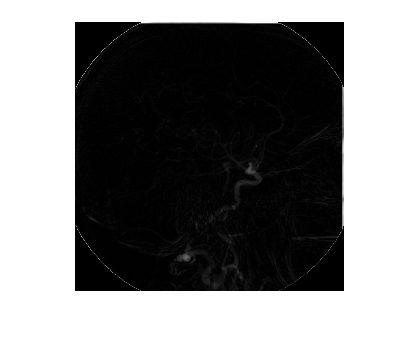

% Setup cost function
costF= @(t) registrationcost(t, live, mask);

% Create the output function with additional parameters
outfun = @(x, optimVals, state) regOutFun(x, optimVals, state, live, mask, param);

% Set optimization options
options = optimset( 'TolFun',1e-3, 'TolX',1e-3);


% Run optimization
t_i= [0,0];
[t_optimal, fval]= fminsearch(costF, t_i, options);

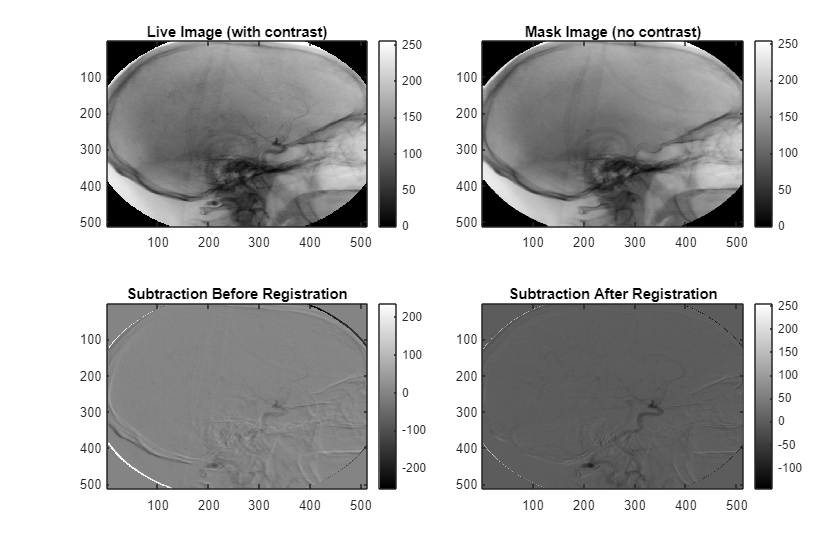


% Apply optimal translation to create registered image
translated = imtranslate(mask, [t_optimal(1), t_optimal(2)], 'OutputView', 'same');

% Calculate final subtraction
diff_after = live - translated;

% Display results
figure('Position', [100 100 1200 800]);
tiledlayout(2,2)

% Original live image
nexttile
imagesc(uint8(live))
colormap('gray')
title('Live Image (with contrast)')
colorbar

% Original mask image
nexttile
imagesc(uint8(mask))
title('Mask Image (no contrast)')
colormap('gray')
colorbar

% Subtraction before registration
nexttile
imagesc(diff_before)
title('Subtraction Before Registration')
colormap('gray')
colorbar

% Subtraction after registration
nexttile
imagesc(diff_after)
title('Subtraction After Registration')
colormap('gray')
colorbar


% Print optimization results
fprintf('\nOptimization Results:\n');


Optimization Results:


fprintf('Inital cost value: %.4f\n', (sum(diff_before.^2, "all")));

Inital cost value: 94956400.0000


fprintf('Optimal translation parameters:\n');

Optimal translation parameters:


fprintf('X translation: %.4f pixels\n', t_optimal(1));

X translation: -2.7436 pixels


fprintf('Y translation: %.4f pixels\n', t_optimal(2));

Y translation: 2.3570 pixels


fprintf('Final cost value: %.4f\n', fval);

Final cost value: 39798779.2723




% Save results
% save('dsa_registration_results.mat', 't_optimal', 'fval', 'output');